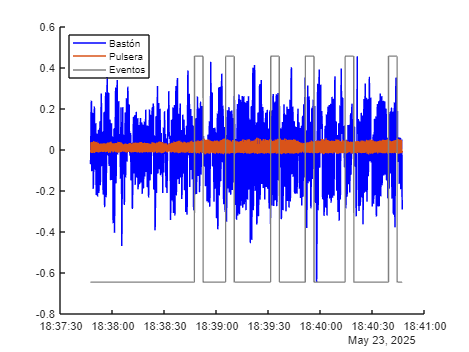

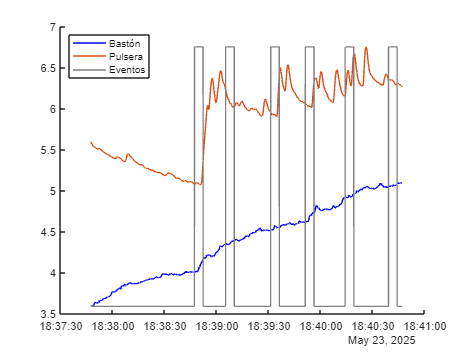

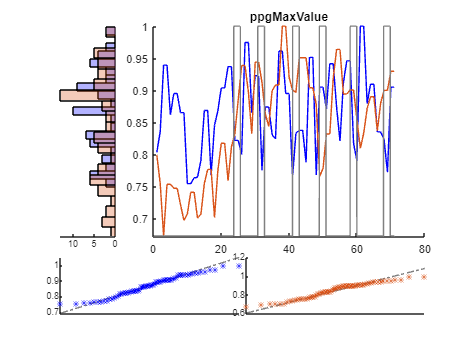

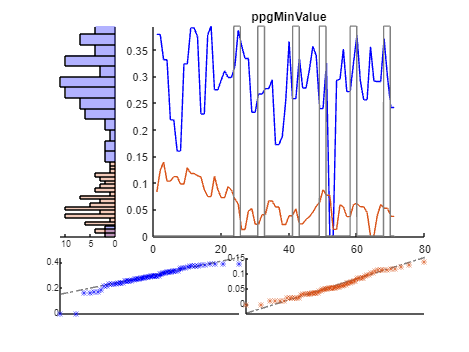

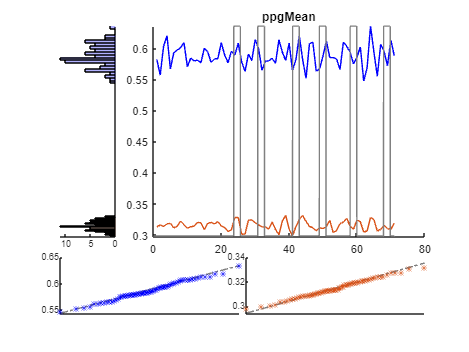

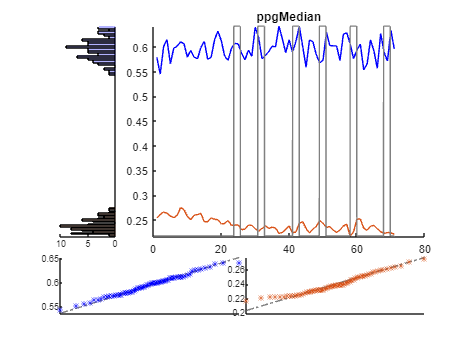

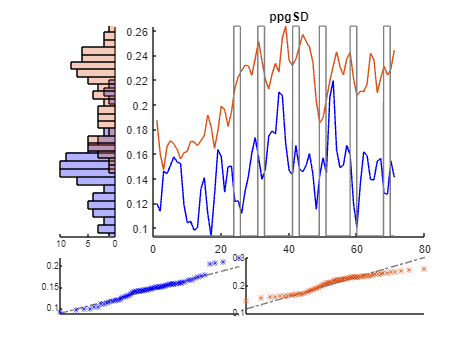

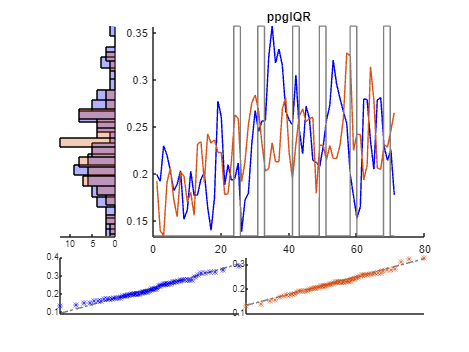

empaticaFeatureTable = 356×24 table
    WinSample    ppgMaxValue    ppgMinValue    ppgMean    ppgMedian     ppgSD     ppgIQR     ppgMAD_Mean    ppgMAD_Median     ppgMD     MeanIBI      HR         SDNN         RMSSD        SDSD       pNN20    pNN50      SI           LF            HF         LFHF      subjectID    experimentID    label
    _________    ___________    ___________    _______    _________    _______    _______    ___________    ____

caneFeatureTable = 356×24 table
    WinSample    ppgMaxValue    ppgMinValue    ppgMean    ppgMedian     ppgSD     ppgIQR     ppgMAD_Mean    ppgMAD_Median     ppgMD     MeanIBI      HR         SDNN        RMSSD        SDSD       pNN20    pNN50      SI           LF            HF         LFHF      subjectID    experimentID    label
    _________    ___________    ___________    _______    _________    _______    _______    ___________    _________

[empaticaFeatureTable, caneFeatureTable] = analiza(19,5,true) %(participante[n], ancho ventana[s], pinta[bool])

function [empaticaFeatureTable, caneFeatureTable] = analiza(n_participant,ancho_ventana,pinta)

% Seleccionamos el participante:
%n_participant=2; Entrada de la función

% Detro de la carpeta, cogemos las señales y el vector del audio
load(sprintf("./data_Participantes/Toma de datos - filtrado (11-06-25)/S%i/signal/S%i_empaticaDataExperiment.mat",n_participant,n_participant));
load(sprintf("./data_Participantes/Toma de datos - filtrado (11-06-25)/S%i/signal/S%i_caneDataExperiment.mat",n_participant,n_participant));
load(sprintf("./data_Participantes/Toma de datos - filtrado (11-06-25)/S%i/S%i_audioEventVector.mat",n_participant,n_participant));

% Procesamos la PPG
t_ventana=ancho_ventana; %20
t_superposicion=t_ventana/2;
[empaticaFeatureTable, caneFeatureTable] = calculateFeatures_DCN(eval(sprintf('S%i_empaticaDataExperiment',n_participant)), ...
                                                                eval(sprintf('S%i_caneDataExperiment', n_participant)), ...
                                                                n_participant, t_ventana, t_superposicion);

if pinta

% Pintamos la gráfica PPG (previo al analisis)
empatica_archivo=sprintf('S%i_empaticaDataExperiment',n_participant);
cane_archivo=sprintf('S%i_caneDataExperiment',n_participant);
audio_archivo=sprintf('S%i_audioEventVector',n_participant);
% PPG
figure
hold on
cane.time=eval(cane_archivo).Music.PPG.TimeStampDate;
cane.data=eval(cane_archivo).Music.PPG.data;
empatica.time=eval(empatica_archivo).Music.PPG.TimeStampDate;
empatica.data=eval(empatica_archivo).Music.PPG.data;
plot(cane.time,cane.data,'Color', 'blue')
plot(empatica.time,empatica.data, 'Color', [0.8500, 0.3250, 0.0980])
maximo=max(max([cane.data;empatica.data]));
minimo=min(min([cane.data;empatica.data]));
plot(eval(audio_archivo).TimeStampDate,eval(audio_archivo).data*(maximo-minimo)+minimo,'Color', [0.5 0.5 0.5])
legend(["Bastón", "Pulsera", "Eventos"],'Location',"northwest")
clear maximo minimo cane empatica
hold off
% GSR
figure
hold on
cane.time=eval(cane_archivo).Music.GSR.TimeStampDate;
cane.data=eval(cane_archivo).Music.GSR.data;
empatica.time=eval(empatica_archivo).Music.GSR.TimeStampDate;
empatica.data=eval(empatica_archivo).Music.GSR.data;
plot(cane.time,cane.data,'Color', 'blue')
plot(empatica.time,empatica.data, 'Color', [0.8500, 0.3250, 0.0980])
maximo=max(max([cane.data;empatica.data]));
minimo=min(min([cane.data;empatica.data]));
plot(eval(audio_archivo).TimeStampDate,eval(audio_archivo).data*(maximo-minimo)+minimo,'Color', [0.5 0.5 0.5])
legend(["Bastón", "Pulsera", "Eventos"],'Location',"northwest")
clear maximo minimo cane empatica
hold off

% Iteramos por cada característica
for carac = string(caneFeatureTable.Properties.VariableNames(2:end-3))
    j=find(caneFeatureTable.Properties.VariableNames(2:end-3)==carac);

    % Cogemos cada característica de la ventanas
    cane.data=caneFeatureTable.(carac)(caneFeatureTable.experimentID==1);
    empatica.data=empaticaFeatureTable.(carac)(empaticaFeatureTable.experimentID==1);


        maximo=max(max([cane.data,empatica.data]));
        minimo=min(min([cane.data,empatica.data]));
    %{
    if(j>10 && j<19)
        SYSP.data=empaticaFeatureTable.SYSP_pre.(empaticaFeatureTable.experimentID==1);
        maximo=max(max([cane.data,empatica.data,SYSP.data]));
        minimo=min(min([cane.data/2,empatica.data/2,SYSP.data]));
    else
        SYSP.data=[];
        maximo=max(max([cane.data/2,empatica.data/2]));
        minimo=min(min([cane.data/2,empatica.data/2]));
    end
    %}

    % Histograma
    figure
    subplot(4,12,[1,26])
    hold on
    histogram(cane.data,20,'FaceColor', 'blue',"FaceAlpha",0.3)
    histogram(empatica.data,20,'FaceColor', [0.8500, 0.3250, 0.0980],"FaceAlpha",0.3)
    %{
    if(~isempty(SYSP.data))
        histogram(SYSP.data,20,'FaceColor', 'magenta',"FaceAlpha",0.3)
    end
    %}
    camroll(90)
    set(gca, 'XTick', [], 'XTickLabel', []);
    if minimo == maximo
        xlim([minimo - 0.1, maximo + 0.1])
    else
        xlim([minimo, maximo])
    end

    % Valores por ventana
    subplot(4,12,[4,36])
    hold on
    plot(cane.data, 'Color', 'blue')
    plot(empatica.data, 'Color', [0.8500, 0.3250, 0.0980])
    %{
    if(~isempty(SYSP.data))
        plot((0:length(SYSP.data)-1).*tiempo_ventana(1),SYSP.data,'Color', 'magenta')
    end
    %}
    timestamps = seconds(eval(audio_archivo).TimeStampDate - eval(audio_archivo).TimeStampDate(1));
    scaledTimestamps = (timestamps*length(cane.data)/timestamps(end));
    plot(scaledTimestamps,eval(audio_archivo).data*(maximo-minimo)+minimo,'Color', [0.5 0.5 0.5])
    %legend(["Cane","Empatica"],'Location',"northwest")
    if minimo == maximo
        ylim([minimo - 0.1, maximo + 0.1])
    else
        ylim([minimo, maximo])
    end
    title(carac)

    
    % Q-Q plot
    subplot(4,12,[37,42])
    p1=qqplot(cane.data);
    p1(1).Marker='*';
    p1(1).MarkerEdgeColor =  'blue';
    p1(2).Color = [0.5 0.5 0.5];
    p1(3).Color = [0.5 0.5 0.5];
    xlabel('');
    ylabel('');
    title('');
    set(gca, 'XTick', [], 'XTickLabel', []);
    subplot(4,12,[43,48])
    p2=qqplot(empatica.data);
    p2(1).Marker='*';
    p2(1).MarkerEdgeColor =  [0.8500, 0.3250, 0.0980];
    p2(2).Color = [0.5 0.5 0.5];
    p2(3).Color = [0.5 0.5 0.5];
    xlabel('');
    ylabel('');
    title('');
    set(gca, 'XTick', [], 'XTickLabel', []);
    hold off

end

end


end